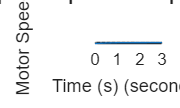

clc; clear; close all;

K = 1;
tau = 0.5;

G = tf(K,[tau 1]);

figure;
step(G);
title('Open Loop Motor Step Response');
xlabel('Time (s)');
ylabel('Motor Speed');

if ~exist('results','dir')
    mkdir('results');
end

saveas(gcf,'results/open_loop_response.png');